clc
clear
close all

## DTFT

生成$R_5 \left(n\right)$

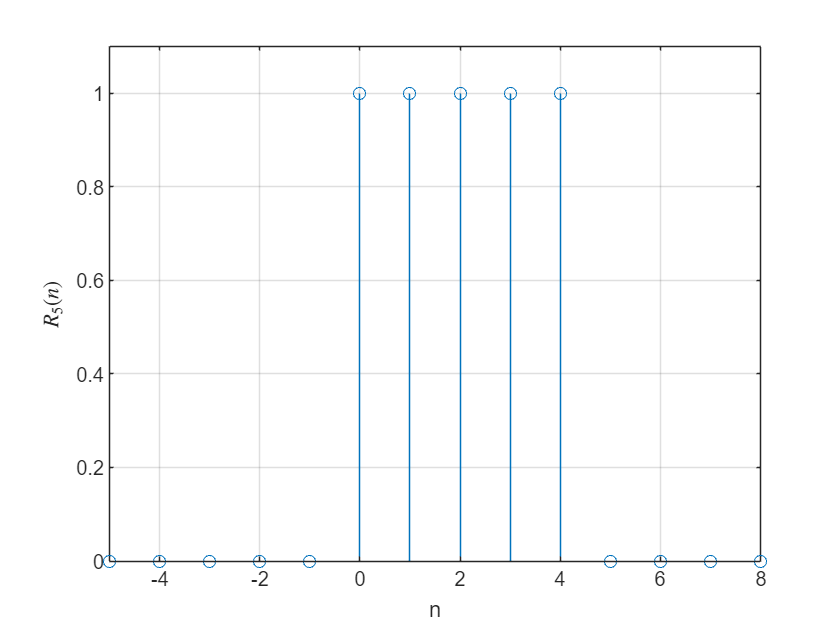

[x,n] =rec_seq(0,5,-5,8); 
stem(n,x);
grid on
axis([-5,8,0,1.1]);
xlabel('n');
ylabel('$R_5(n)$',Interpreter='latex')

计算R(n)的DTFT

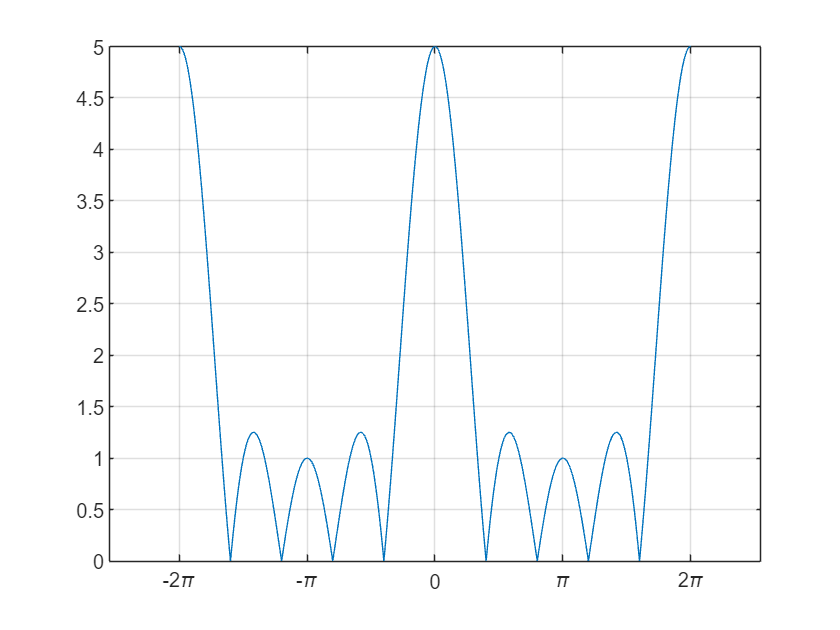

w = -2*pi:(2*pi)/1000:2*pi;
X = (1-exp(-1i*w*length(x(x==1))))./(1-exp(-1i*w)); % R(n)的DTFT
magX = abs(X); % X的幅值
angX = angle(X);% X的相位
plot(w,magX);
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
grid on

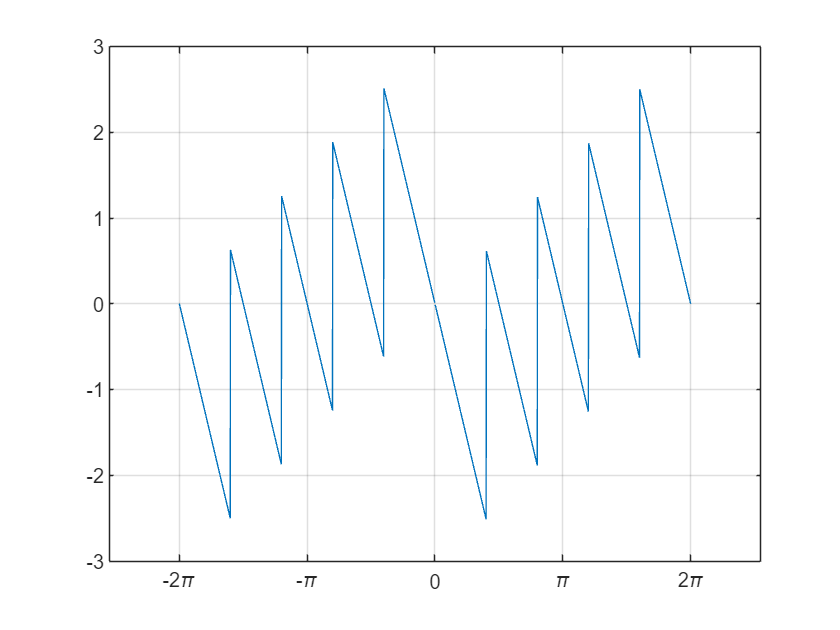

plot(w,angX);
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
grid on

### 差分方程

a  = 0.8

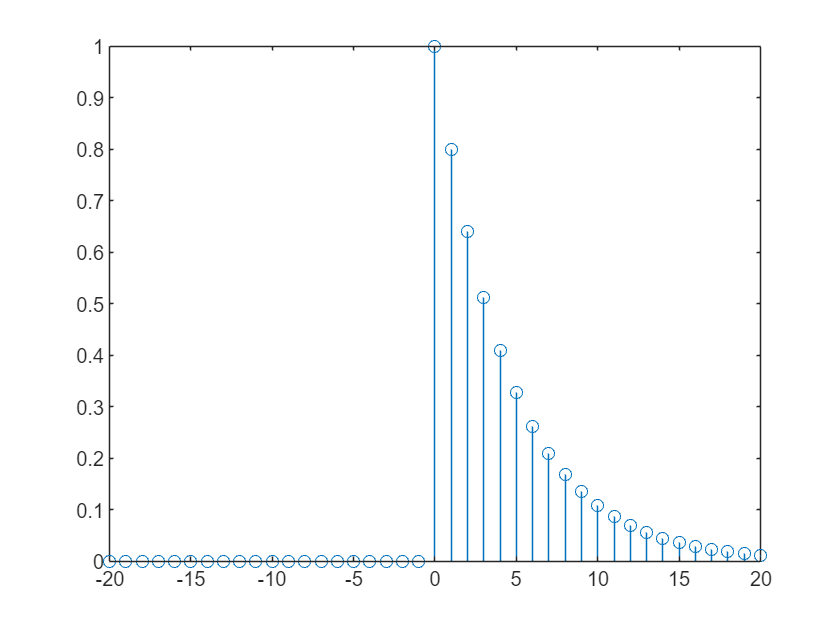

a = [1,-0.8];
b = 1;
n = -20:1:20;
h = impz(b,a,n);
stem(n,h)

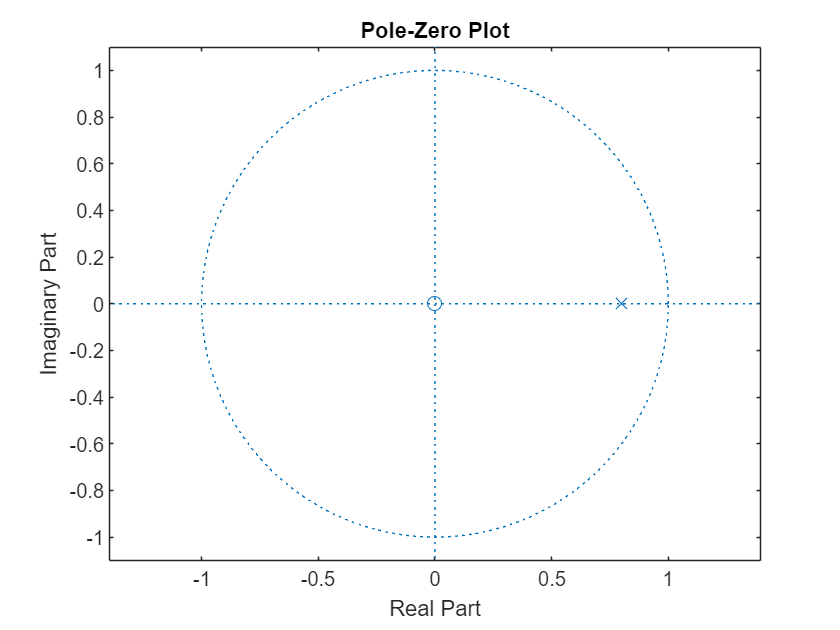

zplane(b,a)

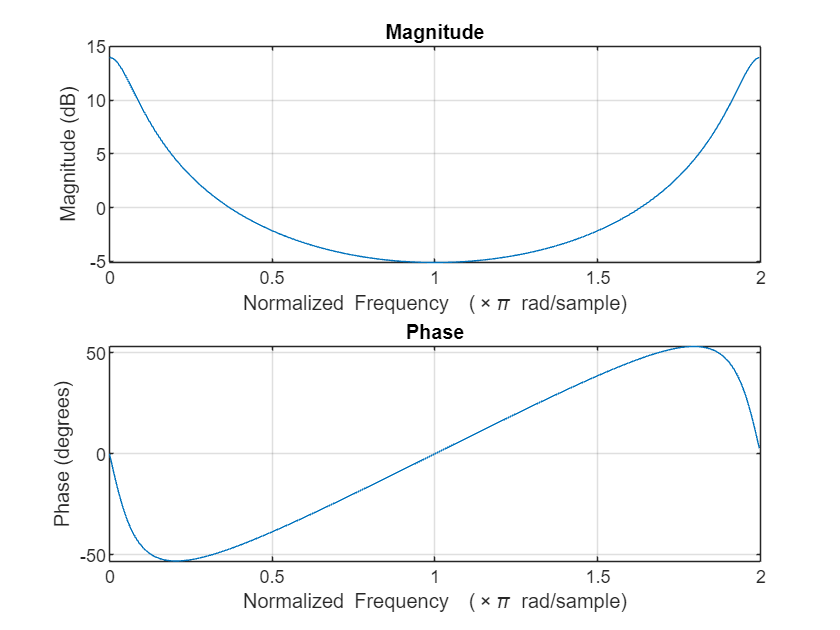

freqz(b, a,'whole');

a = -0.8

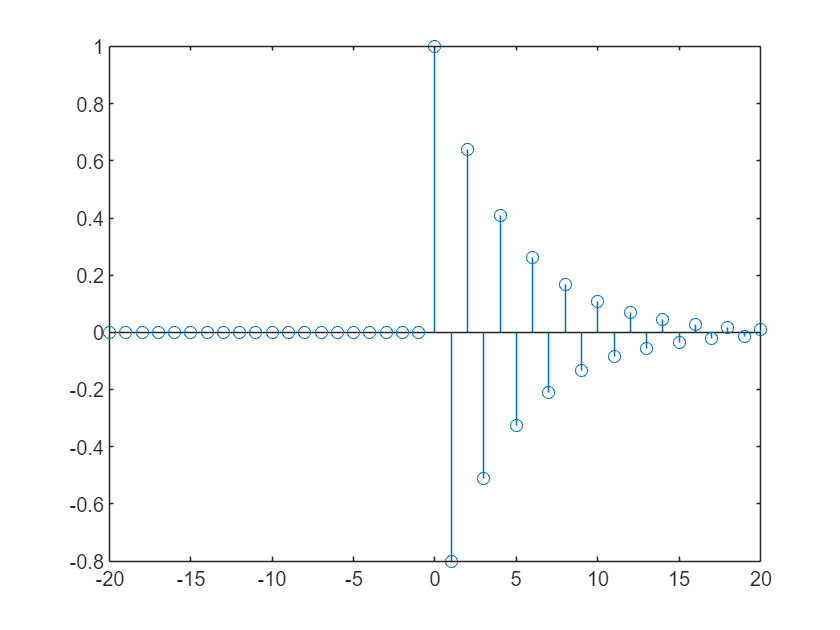

a = [1,0.8];
b = 1;
n = -20:1:20;
h = impz(b,a,n);
stem(n,h)

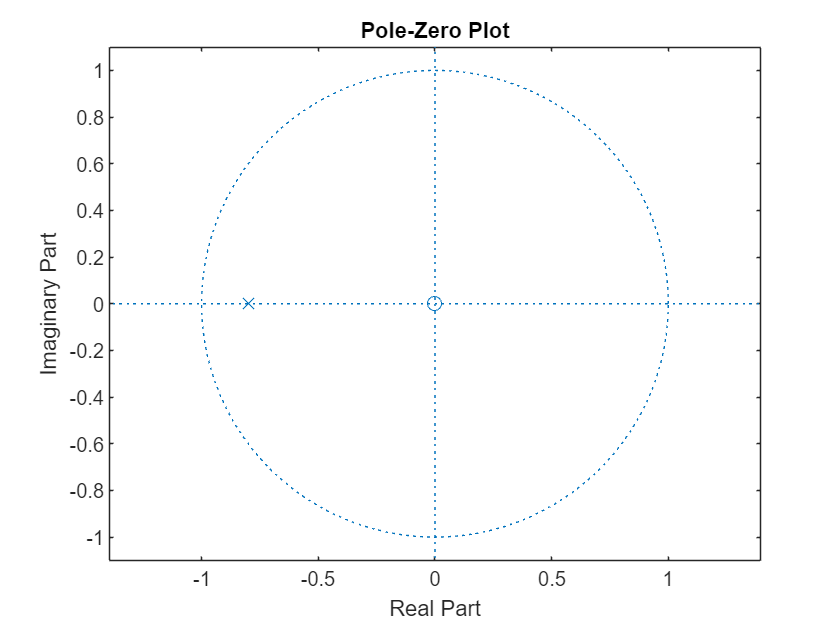

zplane(b,a)

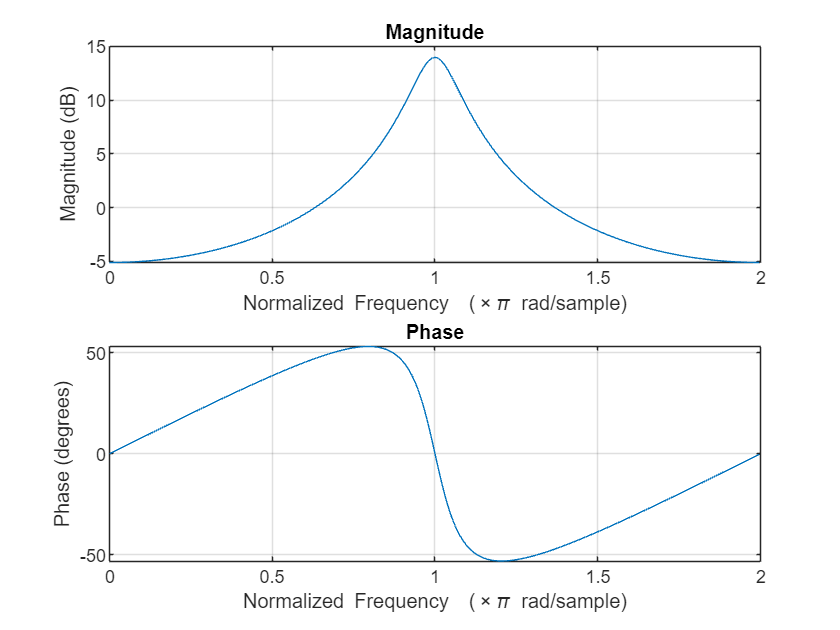

freqz(b, a,'whole');

function [x,n] = rec_seq(n0,n3,n1,n2)
    % 生成 n1~n2 的矩形序列，n0, n3-1 处跳变
    n = n1:n2;
    x = ((n-n0)>=0) - ((n-n3)>=0);
end